fis = readfis('FuzzyLogic.fis');
sug_fis = convertToSugeno(fis);

%needs to be done after converted to sugeno
fis = convertToStruct(fis);


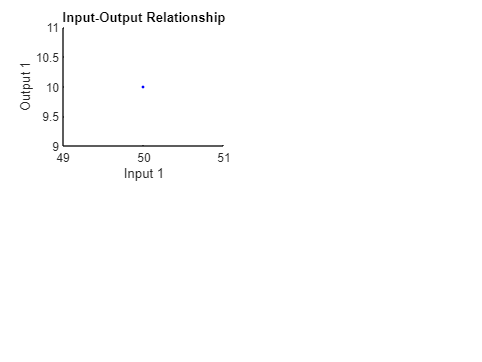

% Generate random input data
num_samples = 100;
%input_data = rand(num_samples, 1); % Random input data with 5 inputs

% Apply the FIS to get the output
%output_data = zeros(num_samples, 3); % Preallocate output data
%for i = 1:num_samples
%    output_data(i, :) = evalfis(input_data(i, :), fis);
%end

%input_data = linspace(-3, 3, 100)';
%output_data = sin(input_data) + 0.5 * randn(size(input_data));

input_data = [50, 100, 70, 18, 1];
output_data = [10, 0, 100, 12, 3];


% Plot the input-output relationship
figure;
subplot(2, 2, 1);
scatter(input_data(:, 1), output_data(:, 1), 'b.');
xlabel('Input 1');
ylabel('Output 1');
title('Input-Output Relationship');

Let's start the optimization

% Define GA parameters
population_size = 50;
num_generations = 100;
mutation_rate = 0.1;

% Initialize population
num_variables = 1; % Assuming all inputs have the same number of membership functions
chromosome_length = 3 * num_variables * 3; % Assuming 3 membership functions for each input variable
population = rand(population_size, chromosome_length);

input_var_index = 1

input_var_index = 1

output_var_index = 1

output_var_index = 1


% Get the membership functions for the selected input and output variables
input_mfs = fis.input(input_var_index).mf;
output_mfs = fis.output(output_var_index).mf;

% Encode the problem by flattening the membership function parameters
num_input_mfs = numel(input_mfs);
num_output_mfs = numel(output_mfs);
chromosome_length = (num_input_mfs * 2) + (num_output_mfs * 2); % Center and width for each MF

% Define the bounds for the membership function parameters
lb = zeros(1, chromosome_length); % Lower bounds
ub = ones(1, chromosome_length); % Upper bounds

% Define the fitness function
fitness_fun = @(chromosome) evaluateFitness(chromosome, fis, input_data, output_data, ...
                                            input_var_index, output_var_index);

% Define the options for the genetic algorithm
options = optimoptions('ga', 'PopulationSize', 50, 'MaxGenerations', 100, ...
                       'CrossoverFraction', 0.8, 'MutationFcn', {@mutationadaptfeasible, 0.1});
% Run the genetic algorithm
[best_chromosome, best_fitness] = ga(fitness_fun, chromosome_length, [], [], [], [], lb, ub, [], options);

input_data =     50   100    70    18     1


Incorrect number of fields in expression 'fis.input.mf': expected 3 but found 4.

Error in evaluateNonhomogenousFIS_double_mex

Error in fuzzy.internal.utility.evalfis (line 121)
        [varargout{1:nargout}] = fuzzy.internal.codegen. ...

Error in evalfis (


% Update the FIS with the optimized membership functions
fis = updateFIS(fis, best_chromosome, input_var_index, output_var_index);

% Helper functions

function fitness = evaluateFitness(chromosome, fis, input_data, output_data, input_var_index, output_var_index)
    % Update the FIS with the chromosome
    fis = updateFIS(fis, chromosome, input_var_index, output_var_index);
    
    % Evaluate the FIS with the input data
    fis_output = evalfis(fis, input_data);
    
    % Calculate the fitness based on the error between fis_output and output_data
    fitness = -mse(fis_output, output_data); % Maximize the negative mean squared error
end

function fis = updateFIS(fis, chromosome, input_var_index, output_var_index)
    % Get the membership functions for the selected input and output variables
    input_mfs = fis.input(input_var_index).mf;
    output_mfs = fis.output(output_var_index).mf;
    
    num_input_mfs = numel(input_mfs);
    num_output_mfs = numel(output_mfs);
    
    % Update the input membership function parameters
    input_mf_params = chromosome(1:num_input_mfs*2);
    for i = 1:num_input_mfs
        input_mfs(i).Parameters = input_mf_params([(i-1)*2+1, (i-1)*2+2]);
    end
    fis.input(input_var_index).mf = input_mfs;
    
    % Update the output membership function parameters
    output_mf_params = chromosome((num_input_mfs*2+1):end);
    for i = 1:num_output_mfs
        output_mfs(i).Parameters = output_mf_params([(i-1)*2+1, (i-1)*2+2]);
    end
    fis.output(output_var_index).mf = output_mfs;
end
function fitness = evaluate_fitness(fis, input_data, output_data, params)
    % Update membership functions based on the parameters
    updated_fis = update_membership_functions(fis, params);
    
    % Evaluate FLC performance using input-output data
    output = evalfis(updated_fis, input_data);
    
    % Calculate fitness (e.g., mean squared error)
    fitness = -mean((output - output_data).^2); % Negative MSE to maximize fitness
end

% Function to update membership functions
function updated_fis = update_membership_functions(fis, params)
    % Update membership functions of input variables
    fis.input(1).mf(1).params = params(1);
    fis.input(1).mf(2).params = params(2);
    
    % Update membership functions of output variables
    % Modify according to your FIS structure
    
    updated_fis = fis;
end

% Load the original FIS

original_fis = readfis('FuzzyLogic.fis');

% Generate sample input data

input_data = linspace(0, 10, 100);

% Evaluate output of original FLC

original_output = evalfis(input_data, original_fis);

% Update membership functions with optimized parameters

updated_fis = update_membership_functions(original_fis, opt_params);

% Evaluate output of optimized FLC

optimized_output = evalfis(input_data, updated_fis);

% Plot results

figure;

plot(input_data, original_output, 'b', 'LineWidth', 2);

hold on;

plot(input_data, optimized_output, 'r--', 'LineWidth', 2);

xlabel('Input');

ylabel('Output');

legend('Original FLC', 'Optimized FLC');

title('Comparison of Original and Optimized FLC');

grid on;

hold off;